# Sistema Realimentados

# EP25 - Projeto do controlador proporcional derivativo

Data: 13 de junho

ARTHUR LORENCINI BERGAMASCHI

PEDRO GABRIEL GAMBERT DA SILVA

## Questão 1

Seja a FT 


$$G\left(s\right)=\frac{2}{\left(s+1\right)\left(s+1\right)\left(5s+1\right)}$$


## Projete um controlador C1 do tipo PI que atenda as especificações:

• Erro nulo em regime para entrada degrau

• Tempo de estabelecimento ≤40 segundos.

• Sobrelevação menor que 40%

s = tf('s');
g1 = 2/((s+1)*(s+1)*(5*s+1));

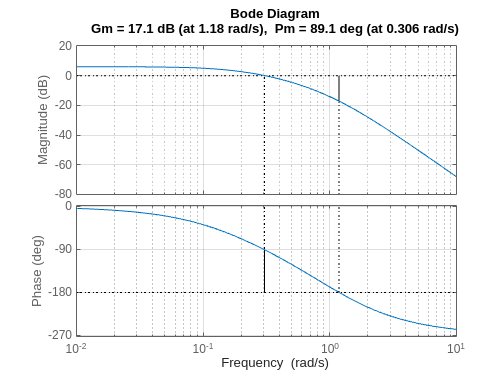

margin(g1);
grid;

Ao analisar o gráfico de bode acima, vimos que a margem de fase está relativamente grande.

Portanto, vamos adicionar um ganho proporcional para diminuirmos a margem de fase com o intuito de tornar o sistema um pouco mais rápido. Vamos esolher uma menor margem de fase, de em torno de 60 graus.

Nota-se que que se a curva de módulo deslocar 4.5 dB para cima, a margem de fase passa a ser de aproximadamente 60 graus.

Poranto, para que a curva de módulo tenha o deslocamento necessário, o ganho Kp deve ser:


$$k_p ={10}^{\left(\frac{4\ldotp 5}{20}\right)} \to k_p =1\ldotp 67$$


Portanto:

kp = 1.67;
G1=(kp*g1);

Plotando o gráfico de bode da função com o ganho kp:

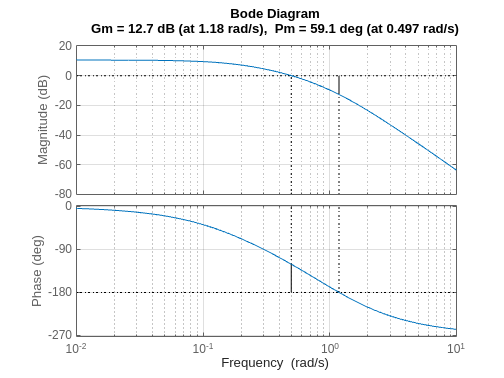

margin(G1); grid;

Analisando o gráfico de bode acima, é possível notar que atingimos a margem da fase desejada e que a frequência de cruzamento de ganho passou para aprocimadamente 0.5 rad/s.

A partir dessa frequência wg, fizemos as simulações variando a posição do zero do controlador PI.

Adicionamos então o zero do PI na posição $\frac{\omega_g }{10}\;e\;\frac{\omega_g }{5}\;$

wg = 0.5;
ki_1 = kp*wg/10

ki_1 = 0.0835

ki_2 = kp*wg/5

ki_2 = 0.1670

ki_3 = kp*wg/7.5

ki_3 = 0.1113

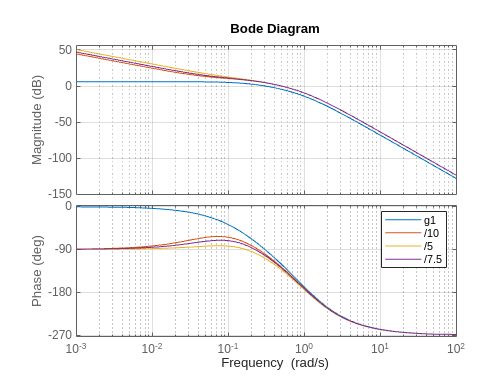

c1_1 = kp + ki_1/s;
c1_2 = kp + ki_2/s;
c1_3 = kp + ki_3/s;
bode(g1,c1_1*g1,c1_2*g1, c1_3*g1); grid;
legend('g1','/10','/5','/7.5')

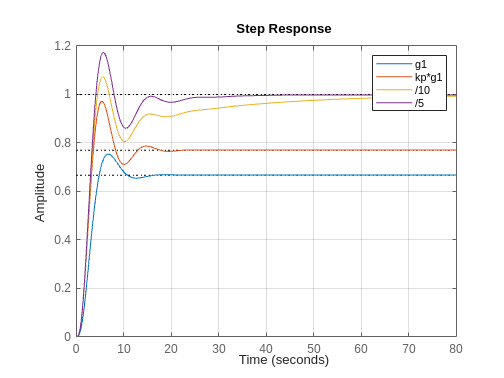

c1 = c1_2;
m=feedback(g1,1);
m_0 = feedback (G1,1);
m1_1 = feedback(c1_1*g1,1);
m1_2 = feedback(c1_2*g1,1);
m1_3 = feedback(c1_3*g1,1);
step(m,m_0,m1_1,m1_2);grid;
legend('g1','kp*g1','/10','/5', '/7.5')

Nota-se que a adição do zero na posição de uma década antes da frequência de cruzamento de ganho wg encontrada anteriormente, a condição imposta de tempo de estabelecimento não é atendida.

É possível ainda notar, que apenas aumento o ganho kp, a condição de sobreelevação não é atendida, uma vez que quanto maior o kp, maior a sobreelevação e menor a estabilidade relativa.

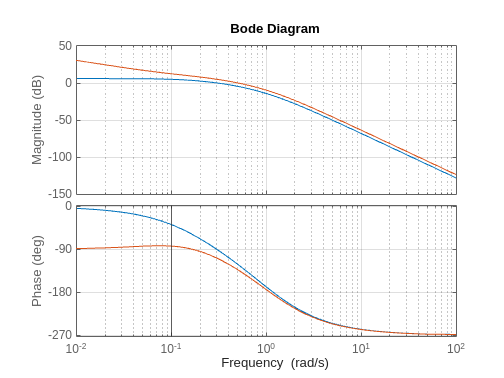

m1 = m1_2;
bode(g1, c1*g1);grid; 
xline(ki_2/kp);

Mostre no gráfico a localização do zero do PI.

Analisando os gráficos de bode acima pode-se observar que a adição do zero do controlador PI fez com que a margem de fase diminuisse ainda mais (se compadrado com a margem de fase do sistema já com o ganho kp que era de aproximadamente 60 graus). Fazendo com que o erro em regime seja nulo.

## Projete um controlador C2 do tipo PD que junto com C1 atenda as especificações:

• Erro nulo em regime para entrada degrau

• Tempo de estabelecimento ≤20 segundos.

• Sobrelevação menor que 5%

Mostre o gráfico de Bode de C1G e de C2C1G, explicando o projeto e o efeito do PD sobre a Margem de fase.

Mostre no gráfico a localização do zero do PI e do PD.

Primeiramente analisamos o gráfico de bode do sistema com controlador PI.

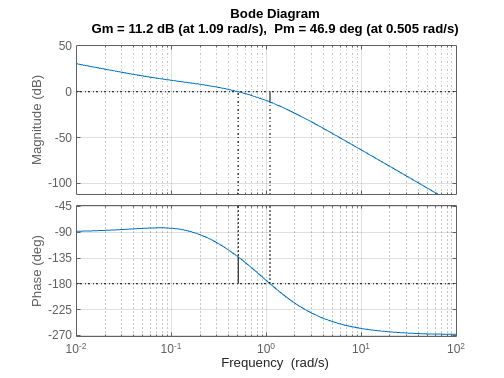

g2 = c1*g1;
margin(g2); grid;

Vamos aumentar o ganho para melhorar o tempo de resposta, para atender a condição imposta.

Portanto, vamos adicionar um ganho proporcional para diminuirmos a margem de fase com o intuito de tornar o sistema um pouco mais rápido. Vamos esolher uma menor margem de fase, de em torno de 28 graus.

Nota-se que que se a curva de módulo deslocar aproximadamente 4 dB para cima, a margem de fase passa a ser de aproximadamente 28 graus.

Logo, adicionamos o ganho $k_p ={10}^{\left(\frac{4}{20}\right)} \to k_p =1\ldotp 6$

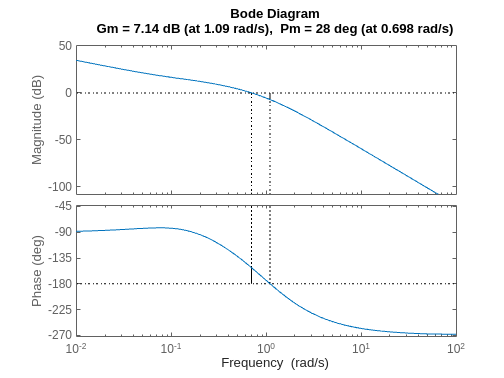

kp2 = 1.6;
margin(kp2*g2)

Com o tempo de estabelecimento atendido, adicionaremos o zero do controladro P2 com o intuito de aumentar a margem de fase e atender a condição de sobreelevação imposta.

Optmaos por simular o controlador PD variando a posição do seu zero.

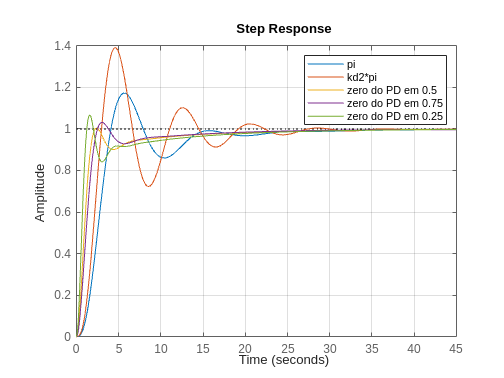

F_1 = 1;
F_2 = 1.5;
F_3 = 0.5;
zero = wg;
zero_pd1 = zero*F_1;
zero_pd2 = zero*F_2;
zero_pd3 = zero*F_3;
kd1 = kp2/zero_pd1;
kd2 = kp2/zero_pd2;
kd3 = kp2/zero_pd3;

% Montando o controlador
c2_1 = kp2 + kd1*s;
c2_2 = kp2 + kd2*s;
c2_3 = kp2 + kd3*s;
m2 = feedback(kp2*g2,1);
m3 = feedback(c2_1*g2,1);
m4 = feedback(c2_2*g2,1);
m5 = feedback(c2_3*g2,1);
step(m1,m2,m3,m4,m5);grid;
legend('pi','kd2*pi','zero do PD em 0.5', 'zero do PD em 0.75','zero do PD em 0.25')

Analisando o gráfico de resposta acima, conclui-se que quanto mais próximo o zero do PD está do zero do PI, menor é a sobreelevação.

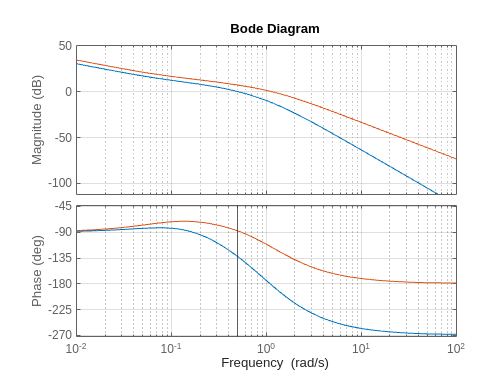

% Mostre o gráfico de Bode de C1G e de C2C1G, explicando o projeto e o efeito do PD sobre a Margem de fase.
bodeplot(g2,c2_1*g2);grid;
xline(zero_pd1)

Analisando o gáfico de bode acima, nota-se que a adição de mais um zero no sistema (PD), acarretou em uma maior margem de fase, fazendo com que a resposta tenha menor sobreelevação e atenda a condição imposta.